# Team 3: Hexapod Robot 1m Obstacle Threshold

#### Gary Encinas, Justin Fossum, Jason Munger, and Mithulesh Ramkumar

## Building The Model

This code was derived and adjusted from our group script called "Hexapod_Robot_Full_Model.mlx" in which we built the full rigid body model of the robot with STL meshes for the first time.

### Environment Setup

First, we should remove items from workspace, freeing up system memory, and clear current command window.

clf('reset'); %Clear current figure window
clear; % Remove items from workspace, freeing up system memory
clc; % Clear current command window

### Building the Rigid Tree Model

When building this model, the leg length visual meshes are reused, so rather than the full string path every time, we have listed them all as variables in the beginning. Keeping true with that fashion, the DH parameters are only changed by a ratio of $\frac{\pi }{3}$ each new leg so there is a count variable that can be called to index the leg creations.

body_mesh = "..\Robot CAD\STL\Body_Link.STL";
link1_vmesh = "..\Robot CAD\STL\Link_One_L2Out.STL";
link2_vmesh = "..\Robot CAD\STL\Link_Two_640_L3Out.STL";
link3_vmesh = "..\Robot CAD\STL\Link_Three_960_EEOut.STL";

link3_vmesh_leg12 = "..\Robot CAD\STL\Link_Three_960_EEOut_MovedFoot_500.STL";

count = 1; % Counting variable for itterating through the legs with the order being 2, 1, 3, 5, 6, 4 for leg names.

a = [0.625 0 0.640 0.960]; % Link lengths as a 1:1.5 leg ratio.
alpha = [0 pi/2 0 -pi/2];
d = [0 0 0 0];
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];

%Building The Robot by creating a rigid body tree
full_robot = robotics.RigidBodyTree; %Sets rigid body tree to be called robot for callback use

% Define the bodies and their joints
leg_1 = robotics.RigidBody('leg_1'); %Create Leg 1 Origin of the robot.
leg_2 = robotics.RigidBody('leg_2'); %Create Leg 2 Origin of the robot.
leg_3 = robotics.RigidBody('leg_3'); %Create Leg 3 Origin of the robot.
leg_4 = robotics.RigidBody('leg_4'); %Create Leg 4 Origin of the robot.
leg_5 = robotics.RigidBody('leg_5'); %Create Leg 5 Origin of the robot.
leg_6 = robotics.RigidBody('leg_6'); %Create Leg 6 Origin of the robot.

leg1_jnt1 = robotics.Joint('leg1_jnt1','fixed'); %Create a fixed joint.
leg2_jnt1 = robotics.Joint('leg2_jnt1','fixed'); %Create a fixed joint.
leg3_jnt1 = robotics.Joint('leg3_jnt1','fixed'); %Create a fixed joint.
leg4_jnt1 = robotics.Joint('leg4_jnt1','fixed'); %Create a fixed joint.
leg5_jnt1 = robotics.Joint('leg5_jnt1','fixed'); %Create a fixed joint.
leg6_jnt1 = robotics.Joint('leg6_jnt1','fixed'); %Create a fixed joint.

leg1_link1 = robotics.RigidBody('leg1_link1'); %Create Link 1 of the leg 1.
leg2_link1 = robotics.RigidBody('leg2_link1'); %Create Link 1 of the leg 2.
leg3_link1 = robotics.RigidBody('leg3_link1'); %Create Link 1 of the leg 3.
leg4_link1 = robotics.RigidBody('leg4_link1'); %Create Link 1 of the leg 4.
leg5_link1 = robotics.RigidBody('leg5_link1'); %Create Link 1 of the leg 5.
leg6_link1 = robotics.RigidBody('leg6_link1'); %Create Link 1 of the leg 6.

leg1_jnt2 = robotics.Joint('leg1_jnt2','revolute'); %Create a revolute joint.
leg2_jnt2 = robotics.Joint('leg2_jnt2','revolute'); %Create a revolute joint.
leg3_jnt2 = robotics.Joint('leg3_jnt2','revolute'); %Create a revolute joint.
leg4_jnt2 = robotics.Joint('leg4_jnt2','revolute'); %Create a revolute joint.
leg5_jnt2 = robotics.Joint('leg5_jnt2','revolute'); %Create a revolute joint.
leg6_jnt2 = robotics.Joint('leg6_jnt2','revolute'); %Create a revolute joint.

leg1_link2 = robotics.RigidBody('leg1_link2'); %Create Link 2 of the leg 1.
leg2_link2 = robotics.RigidBody('leg2_link2'); %Create Link 2 of the leg 2.
leg3_link2 = robotics.RigidBody('leg3_link2'); %Create Link 2 of the leg 3.
leg4_link2 = robotics.RigidBody('leg4_link2'); %Create Link 2 of the leg 4.
leg5_link2 = robotics.RigidBody('leg5_link2'); %Create Link 2 of the leg 5.
leg6_link2 = robotics.RigidBody('leg6_link2'); %Create Link 2 of the leg 6.

leg1_jnt3 = robotics.Joint('leg1_jnt3','revolute'); %Create a revolute joint.
leg2_jnt3 = robotics.Joint('leg2_jnt3','revolute'); %Create a revolute joint.
leg3_jnt3 = robotics.Joint('leg3_jnt3','revolute'); %Create a revolute joint.
leg4_jnt3 = robotics.Joint('leg4_jnt3','revolute'); %Create a revolute joint.
leg5_jnt3 = robotics.Joint('leg5_jnt3','revolute'); %Create a revolute joint.
leg6_jnt3 = robotics.Joint('leg6_jnt3','revolute'); %Create a revolute joint.

leg1_link3 = robotics.RigidBody('leg1_link3'); %Create Link 3 of the leg 1.
leg2_link3 = robotics.RigidBody('leg2_link3'); %Create Link 3 of the leg 2.
leg3_link3 = robotics.RigidBody('leg3_link3'); %Create Link 3 of the leg 3.
leg4_link3 = robotics.RigidBody('leg4_link3'); %Create Link 3 of the leg 4.
leg5_link3 = robotics.RigidBody('leg5_link3'); %Create Link 3 of the leg 5.
leg6_link3 = robotics.RigidBody('leg6_link3'); %Create Link 3 of the leg 6.

leg1_jnt4 = robotics.Joint('leg1_jnt4','revolute'); %Create a revolute joint.
leg2_jnt4 = robotics.Joint('leg2_jnt4','revolute'); %Create a revolute joint.
leg3_jnt4 = robotics.Joint('leg3_jnt4','revolute'); %Create a revolute joint.
leg4_jnt4 = robotics.Joint('leg4_jnt4','revolute'); %Create a revolute joint.
leg5_jnt4 = robotics.Joint('leg5_jnt4','revolute'); %Create a revolute joint.
leg6_jnt4 = robotics.Joint('leg6_jnt4','revolute'); %Create a revolute joint.

% Specify the body-to-body transformation using DH parameters
setFixedTransform(leg2_jnt1,DHparams(1,:),'dh');
count = count + 1; % Index the count variable for the next leg origin.
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];
setFixedTransform(leg1_jnt1,DHparams(1,:),'dh');
count = count + 1; % Index the count variable for the next leg origin.
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];
setFixedTransform(leg3_jnt1,DHparams(1,:),'dh');
count = count + 1; % Index the count variable for the next leg origin.
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];
setFixedTransform(leg5_jnt1,DHparams(1,:),'dh');
count = count + 1; % Index the count variable for the next leg origin.
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];
setFixedTransform(leg6_jnt1,DHparams(1,:),'dh');
count = count + 1; % Index the count variable for the next leg origin.
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];
setFixedTransform(leg4_jnt1,DHparams(1,:),'dh');
count = count + 1; % Index the count variable for the next leg origin.
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];

setFixedTransform(leg1_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg1_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg1_jnt4,DHparams(4,:),'dh');

setFixedTransform(leg2_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg2_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg2_jnt4,DHparams(4,:),'dh');

setFixedTransform(leg3_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg3_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg3_jnt4,DHparams(4,:),'dh');

setFixedTransform(leg4_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg4_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg4_jnt4,DHparams(4,:),'dh');

setFixedTransform(leg5_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg5_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg5_jnt4,DHparams(4,:),'dh');

setFixedTransform(leg6_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg6_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg6_jnt4,DHparams(4,:),'dh');

% Specify the body joints
leg_1.Joint = leg1_jnt1;
leg_2.Joint = leg2_jnt1;
leg_3.Joint = leg3_jnt1;
leg_4.Joint = leg4_jnt1;
leg_5.Joint = leg5_jnt1;
leg_6.Joint = leg6_jnt1;

leg1_link1.Joint = leg1_jnt2;
leg1_link2.Joint = leg1_jnt3;
leg1_link3.Joint = leg1_jnt4;

leg2_link1.Joint = leg2_jnt2;
leg2_link2.Joint = leg2_jnt3;
leg2_link3.Joint = leg2_jnt4;

leg3_link1.Joint = leg3_jnt2;
leg3_link2.Joint = leg3_jnt3;
leg3_link3.Joint = leg3_jnt4;

leg4_link1.Joint = leg4_jnt2;
leg4_link2.Joint = leg4_jnt3;
leg4_link3.Joint = leg4_jnt4;

leg5_link1.Joint = leg5_jnt2;
leg5_link2.Joint = leg5_jnt3;
leg5_link3.Joint = leg5_jnt4;

leg6_link1.Joint = leg6_jnt2;
leg6_link2.Joint = leg6_jnt3;
leg6_link3.Joint = leg6_jnt4;

% Add the STL visual to the body
addVisual(leg_2, "Mesh", body_mesh);

% Add the STL visual to the first links
addVisual(leg1_link1, "Mesh", link1_vmesh);
addVisual(leg2_link1, "Mesh", link1_vmesh);
addVisual(leg3_link1, "Mesh", link1_vmesh);
addVisual(leg4_link1, "Mesh", link1_vmesh);
addVisual(leg5_link1, "Mesh", link1_vmesh);
addVisual(leg6_link1, "Mesh", link1_vmesh);

% Add the STL visual to the second links
addVisual(leg1_link2, "Mesh", link2_vmesh);
addVisual(leg2_link2, "Mesh", link2_vmesh);
addVisual(leg3_link2, "Mesh", link2_vmesh);
addVisual(leg4_link2, "Mesh", link2_vmesh);
addVisual(leg5_link2, "Mesh", link2_vmesh);
addVisual(leg6_link2, "Mesh", link2_vmesh);

% Add the STL visual to the third links
addVisual(leg1_link3, "Mesh", link3_vmesh_leg12);
addVisual(leg2_link3, "Mesh", link3_vmesh_leg12);
addVisual(leg3_link3, "Mesh", link3_vmesh);
addVisual(leg4_link3, "Mesh", link3_vmesh);
addVisual(leg5_link3, "Mesh", link3_vmesh);
addVisual(leg6_link3, "Mesh", link3_vmesh);

% Attach the first Leg
addBody(full_robot,leg_1,'base')
addBody(full_robot,leg1_link1,'leg_1');
addBody(full_robot,leg1_link2,'leg1_link1');
addBody(full_robot,leg1_link3,'leg1_link2');

% Attach the second Leg
addBody(full_robot,leg_2,'base')
addBody(full_robot,leg2_link1,'leg_2');
addBody(full_robot,leg2_link2,'leg2_link1');
addBody(full_robot,leg2_link3,'leg2_link2');

% Attach the third Leg
addBody(full_robot,leg_3,'base')
addBody(full_robot,leg3_link1,'leg_3');
addBody(full_robot,leg3_link2,'leg3_link1');
addBody(full_robot,leg3_link3,'leg3_link2');

% Attach the fourth Leg
addBody(full_robot,leg_4,'base')
addBody(full_robot,leg4_link1,'leg_4');
addBody(full_robot,leg4_link2,'leg4_link1');
addBody(full_robot,leg4_link3,'leg4_link2');

% Attach the fifth Leg
addBody(full_robot,leg_5,'base')
addBody(full_robot,leg5_link1,'leg_5');
addBody(full_robot,leg5_link2,'leg5_link1');
addBody(full_robot,leg5_link3,'leg5_link2');

% Attach the sixth Leg
addBody(full_robot,leg_6,'base')
addBody(full_robot,leg6_link1,'leg_6');
addBody(full_robot,leg6_link2,'leg6_link1');
addBody(full_robot,leg6_link3,'leg6_link2');

full_robot.DataFormat = 'row';
config = homeConfiguration(full_robot);

joint_1_co_ord = [1,1,1,1,1,1;  1,4,7,10,13,16];
joint_2_co_ord = [1,1,1,1,1,1;  2,5,8,11,14,17];
joint_3_co_ord = [1,1,1,1,1,1;  3,6,9,12,15,18];

% Tallest standing height at 0, -38, -52 degrees

% All of joint 1
config(sub2ind(size(config),joint_1_co_ord(1,:),joint_1_co_ord(2,:))) = 0;
% All of joint 2
config(sub2ind(size(config),joint_2_co_ord(1,:),joint_2_co_ord(2,:))) = deg2rad(-38);
% All of joint 3
config(sub2ind(size(config),joint_3_co_ord(1,:),joint_3_co_ord(2,:))) = deg2rad(-52);

% Legs up on obstacle [0.2268, 0.4625, -0.7653]
% Legs 1 and 2 joint 1
config(sub2ind(size(config),joint_1_co_ord(1,1:2),joint_1_co_ord(2,1:2))) = [-0.2268, 0.2268];
% Legs 1 and 2 joint 2
config(sub2ind(size(config),joint_2_co_ord(1,1:2),joint_2_co_ord(2,1:2))) = 0.9338;
% Legs 1 and 2 joint 3
config(sub2ind(size(config),joint_3_co_ord(1,1:2),joint_3_co_ord(2,1:2))) = -2.060;

full_robot_moved = rigidBodyTree;
rb = rigidBody('newBaseForFull_Robot');
rb.Joint.setFixedTransform(make_eular_transform(0,0,1.434,0,0,0));
full_robot_moved.addBody(rb, 'base');
full_robot_moved.addSubtree('newBaseForFull_Robot', full_robot);
full_robot_moved.DataFormat = 'row';

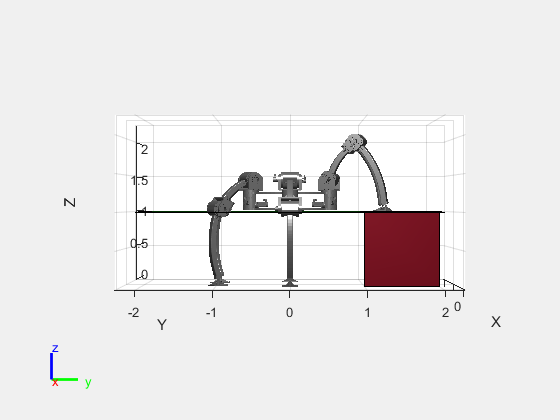

print_figures = true;

figure('Name','1m Obstacle Threshold')
show(full_robot_moved,config,'Collisions','off','Visuals','on',"Frames","off");
xlim([-2.25 2.25])
ylim([-2.25 2.25])
zlim([0, 2.25])
hold on
ox = [1 1 1; 1 1 -1; 1 -1 -1; 1 -1 1];
oy = [1 2 1; 2 2 1; 2 2 2; 1 2 2];
oz = [1 0 1; 1 1 1; 0 1 1; 0 0 1];
obstacle = fill3(ox,oy,oz,'k');
set(obstacle,'FaceColor', '#ab192d');

cx = [2; -2; -2; 2];
cy = [2; 2; -2; -2];
cz = [1;1;1;1];
clearence = patch(cx,cy,cz,'k');
set(clearence,'FaceAlpha',0.3,'FaceColor', 'g');

if print_figures
    set(gcf,'Units','inches'); % Set the units of the figure
    screenposition = get(gcf,'Position'); % Measure the size of the figure
    set(gcf,'PaperPosition', [0 0 screenposition(3:4)],'PaperSize' , (screenposition(3:4))); % Configures the print paper size to fit the figure size
    print('Full Robot at Maximum Walking Height with Front Legs on Obstacle', '-dpng', '-r600') % Save figure as PNG

    view(2); % Top view of the robot
    set(gcf,'Units','inches'); % Set the units of the figure
    screenposition = get(gcf,'Position'); % Measure the size of the figure
    set(gcf,'PaperPosition', [0 0 screenposition(3:4)],'PaperSize' , (screenposition(3:4))); % Configures the print paper size to fit the figure size
    print('Full Robot at Maximum Walking Height with Front Legs on Obstacle - Top View', '-dpng', '-r600') % Save figure as PNG
    
    view(180,0); % Front view of robot
    screenposition = get(gcf,'Position'); % Measure the size of the figure
    set(gcf,'PaperPosition', [0 0 screenposition(3:4)],'PaperSize' , (screenposition(3:4))); % Configures the print paper size to fit the figure size
    print('Full Robot at Maximum Walking Height with Front Legs on Obstacle - Front View', '-dpng', '-r600') % Save figure as PNG
    
    view(90,0); % Side view of the robot
    screenposition = get(gcf,'Position'); % Measure the size of the figure
    set(gcf,'PaperPosition', [0 0 screenposition(3:4)],'PaperSize' , (screenposition(3:4))); % Configures the print paper size to fit the figure size
    print('Full Robot at Maximum Walking Height with Front Legs on Obstacle - Side View', '-dpng', '-r600') % Save figure as PNG
end

function hg_transform = make_eular_transform(x,y,z,a,b,c)
% MAKE_EULAR_TRANSFORM Builds a homogeneous transformation matrix based on
% desired position and rotation. Rotation is in Eular angle.
    arguments
        x (1,1) double {mustBeNumeric, mustBeFinite}
        y (1,1) double {mustBeNumeric, mustBeFinite}
        z (1,1) double {mustBeNumeric, mustBeFinite}
        a (1,1) double {mustBeNumeric, mustBeFinite}
        b (1,1) double {mustBeNumeric, mustBeFinite}
        c (1,1) double {mustBeNumeric, mustBeFinite}
    end

    trans_x = [1, 0, 0, x;
             0, 1, 0, 0;
             0, 0, 1, 0;
             0, 0, 0, 1]; % Translation about the X axis
    trans_y = [1, 0, 0, 0;
             0, 1, 0, y;
             0, 0, 1, 0;
             0, 0, 0, 1]; % Translation about the Y axis
    trans_z = [1, 0, 0, 0;
             0, 1, 0, 0;
             0, 0, 1, z;
             0, 0, 0, 1]; % Translation about the Z axis
    rot_x = [1, 0, 0, 0;
             0, cos(a), -sin(a), 0;
             0, sin(a), cos(a), 0;
             0, 0, 0, 1]; % Rotation about the X axis
    rot_y = [cos(b), 0, sin(b), 0;
             0, 1, 0, 0;
             -sin(b), 0, cos(b), 0;
             0, 0, 0, 1]; % Rotation about the Y axis
    rot_z = [cos(c), -sin(c), 0, 0;
             sin(c), cos(c), 0, 0;
             0, 0, 1, 0;
             0, 0, 0, 1]; % Rotation about the Z axis
    hg_transform = rot_x*rot_y*rot_z*trans_x*trans_y*trans_z; % Built homogeneous transformation matrix
end
